%Image Preprocessing 
image = imread("images/field.jpg"); % Load the image
size(image)

ans =         2048        2048           3


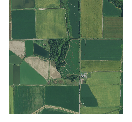

imshow(image); title('Original');

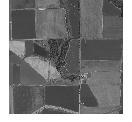


grayImage = im2gray(image); % 1. convert to gray scale
imwrite(grayImage,"grayImage.jpg")
imshow(grayImage); title('Gray');

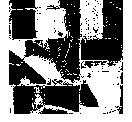

binaryImage = imbinarize(grayImage); % 2. convert to binary image
imshow(binaryImage);

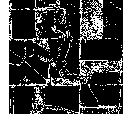

imwrite(binaryImage,"binaryImage.jpg")
% 3. Noise filters
s=strel('disk',5,0); %creates a structuring element disk-shaped, radius of 5
F=imerode(binaryImage,s);%Erode the image by structuring element
erodeImage=binaryImage-F; %Noise filter with erode
imshow(erodeImage); title('Erode');

imwrite(erodeImage,'erodeImage.png');
BW = bwareaopen(erodeImage, 50); % Eliminate any pixels less than 50
imshow(BW); title("bwareaopen")
imwrite(BW,'bwimage.png');


%Image Processing
E = imread('bwimage.png');
%E = imread('erodeImage.png');
[row, col, ~] = size(E);
% 4. Split the image into 4x4
num_img_h = 4; %define number col
num_img_v = 4; %number of rows
row_breaks = round(linspace(1,row,num_img_v+1),0);
col_breaks = round(linspace(1,col,num_img_h+1),0);
loop = 1

loop = 1

%Dividing the image into blocks, each block is named by "temp"
%corresponding to the order number
for iter1 = 1:num_img_v
    iter1
    for iter2 = 1:num_img_h
        iter2
        imwrite(E(row_breaks(iter1):row_breaks(iter1+1),col_breaks(iter2):col_breaks(iter2+1),1:1),['block', num2str(loop), '.png']);
        loop = loop + 1
    end
end

iter1 = 1

iter2 = 1

loop = 2

iter2 = 2

loop = 3

iter2 = 3

loop = 4

iter2 = 4

loop = 5

iter1 = 2

iter2 = 1

loop = 6

iter2 = 2

loop = 7

iter2 = 3

loop = 8

iter2 = 4

loop = 9

iter1 = 3

iter2 = 1

loop = 10

iter2 = 2

loop = 11

iter2 = 3

loop = 12

iter2 = 4

loop = 13

iter1 = 4

iter2 = 1

loop = 14

iter2 = 2

loop = 15

iter2 = 3

loop = 16

iter2 = 4

loop = 17

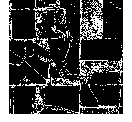

img = 513×513 logical array
   0   0   0   0   0   1   1   1   1   1   1   1   0   0   1   1   1   1   1   0   0   1   1   1   1   1   0   0   1   1   1   0   0   0   0   0   0   0   0   0   1   1   1   0   0   0   0   0   0   0
   0   0   0   0   0   1   1   1   1   1   0   0   0   0   1   1   1   1   1   0   0   0   1   1   1   1   1   0   1   1   1   0   0   0   0   0   0   0   0   0   1   1   1   0   0   0   0   0   0   0
   0   1   1   1   1   1   1   1   1   1   0   0   1   0   0   1   1   1   1   1   0   0   1   1   1   1   1   0   1   1   1   0   0   0   0   0   0   0   0   0   1   1   1   0   0   0   0   0   0   0
   1   1   1   1   1   1   1   1   1   0   0   1   1   0   0   1   1   1   1   1   0   0   1   1   1   1   1   0   1   1   1   0   0   0   0   0   0   0   0   0   1   1   1   0   0   0   0   0   0   0
   1   1   1   1   1   1   1   1   1   0   0   1   1   0   1   1   1   1   1   0   0   0   1   1   1   1   1   1   1   1   1   0   0   0   0   0   0   0   0   0   1   1

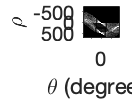

Fig =   Figure (5) with properties:

      Number: 5
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [440 378 560 420]
       Units: 'pixels'

  Show all properties


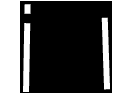

img = 513×513 logical array
   1   1   1   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   1   1   1   1   0   1
   1   1   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   1   1   1   1   1
   1   1   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   1   1   1   1   1
   1   1   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   0   0   0   1   1   1   1   1   1
   1   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   1   1   1   1

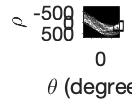

Fig =   Figure (7) with properties:

      Number: 7
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [440 378 560 420]
       Units: 'pixels'

  Show all properties


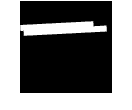

img = 513×512 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0

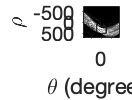

Fig =   Figure (9) with properties:

      Number: 9
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [440 378 560 420]
       Units: 'pixels'

  Show all properties


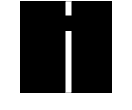

img = 513×513 logical array
   0   0   0   0   0   0   0   0   1   1   1   1   1   0   0   1   1   1   1   1   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   1   1   1   1   0   0   1   1   1   1   1
   0   0   0   0   0   0   0   0   0   1   1   1   1   1   0   0   1   1   1   1   1   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   1   1   1   1   0   0   1   1   1   1   1
   0   0   0   0   0   0   0   0   0   1   1   1   1   1   0   0   1   1   1   1   1   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   1   1   1   1   0   0   1   1   1   1
   0   0   0   0   0   0   0   0   0   1   1   1   1   1   1   0   1   1   1   1   1   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   1   1   1   1   0   0   1   1   1   1
   0   0   0   0   0   0   0   0   0   0   1   1   1   1   1   0   0   1   0   1   1   1   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   1   1

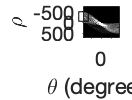

Fig =   Figure (11) with properties:

      Number: 11
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [440 378 560 420]
       Units: 'pixels'

  Show all properties


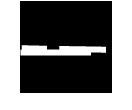

img = 513×513 logical array
   0   0   0   0   0   0   0   0   0   0   0   1   1   0   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   0   1   1   1   1   1   1   1   1   1   1   0   0   0
   0   0   0   0   0   0   0   0   0   0   1   1   0   1   1   1   0   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   0   0   1   1   1   1   1   0   0
   0   0   0   0   0   0   0   0   0   0   1   1   0   1   0   0   0   0   1   1   1   1   1   1   0   1   1   1   1   1   0   1   1   1   1   1   1   1   1   1   1   0   0   1   1   1   1   1   0   0
   0   0   0   0   0   0   0   0   0   0   0   1   0   1   1   1   0   0   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   0   0   1   1   1   1   1   0   1   1   1   1   1   0   0
   0   0   0   0   0   0   0   0   0   1   0   0   0   0   1   1   0   0   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   0   0   1   1   1   1   1

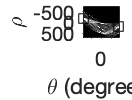

Fig =   Figure (13) with properties:

      Number: 13
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [440 378 560 420]
       Units: 'pixels'

  Show all properties


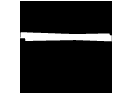

img = 513×513 logical array
   1   1   1   1   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   1   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   0   0   1   1   1   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   0   0   1   1   1   1   1   0   0   0   0   0   0   0   0   0   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   1   1   1   1   1   1   1   1   1   1   1   0   1
   0   0   1   1   1   1   1   0   0   0   0   0   0   0   0   1   1   1   1   1   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   1   1   1   1   1   0   1

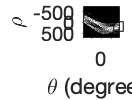

Fig =   Figure (15) with properties:

      Number: 15
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [440 378 560 420]
       Units: 'pixels'

  Show all properties


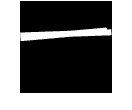

img = 513×512 logical array
   1   1   1   1   1   1   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   1   1   1   1   1   1   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   1   1   1   1   1   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   1   1   1   1   1   1   1   0   0   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   1   1   1   1   1   0   0   0   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0

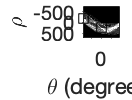

Fig =   Figure (17) with properties:

      Number: 17
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [440 378 560 420]
       Units: 'pixels'

  Show all properties


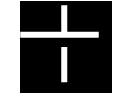

img = 513×513 logical array
   1   0   1   1   1   1   1   0   0   0   0   1   1   1   1   1   1   0   0   1   1   1   1   0   0   0   0   0   1   1   1   1   1   1   1   1   1   0   0   0   0   1   1   1   1   1   0   1   1   1
   1   1   1   1   1   1   0   0   0   0   0   0   1   1   1   1   1   1   1   1   1   1   1   0   0   0   0   0   0   1   1   1   1   0   1   1   1   1   1   1   1   1   1   1   1   1   0   1   1   1
   1   1   1   1   1   1   0   0   0   0   0   0   0   1   1   1   1   1   1   0   1   1   1   1   0   0   0   0   0   0   1   1   1   0   1   1   1   1   1   1   1   1   1   1   1   1   0   1   1   1
   1   1   1   1   1   1   0   0   0   0   0   0   0   1   1   1   1   1   1   0   0   1   1   1   0   0   0   0   0   0   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   0   0   1   1
   1   1   1   1   1   0   0   0   0   0   0   0   0   0   1   1   1   1   1   1   0   1   1   0   0   0   0   0   0   0   1   1   1   1   1   1   1   1   1   1   1   1

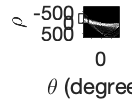

Fig =   Figure (19) with properties:

      Number: 19
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [440 378 560 420]
       Units: 'pixels'

  Show all properties


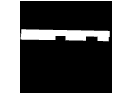

img = 512×513 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0

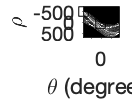

Fig =   Figure (21) with properties:

      Number: 21
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [440 378 560 420]
       Units: 'pixels'

  Show all properties


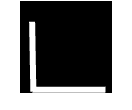

img = 512×513 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   1   1   1   1   1   1   1   1   1   1   1   0   0   0   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   1   1   1   1   1   1   1   1   0   0   0   0   0   1   1   1   1   1   1   1   1   1   1   1   1   1   1   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   1   1   1   1   1   1   1   0   0   0   0   0   0   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   1   1   1   1   1   1   1   0   0   0   0   0   0   0   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   1   1   1   1   1   1   1   1   1   0   0   0   0   0   1   1   1   1   1   1   1

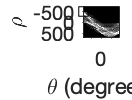

Fig =   Figure (23) with properties:

      Number: 23
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [440 378 560 420]
       Units: 'pixels'

  Show all properties


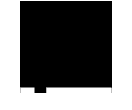

img = 512×512 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0

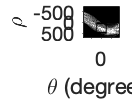

Fig =   Figure (25) with properties:

      Number: 25
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [440 378 560 420]
       Units: 'pixels'

  Show all properties


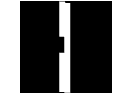

img = 512×513 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0

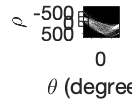

Fig =   Figure (27) with properties:

      Number: 27
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [440 378 560 420]
       Units: 'pixels'

  Show all properties


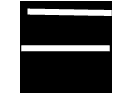

img = 513×513 logical array
   0   1   1   1   1   0   0   1   1   1   1   1   1   1   0   1   0   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   0   0   1   0   0   0   0   0   1   1   1   1   1   1   0   0   1   0   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   0   0
   0   0   0   0   0   0   0   0   0   1   1   1   1   1   0   0   1   1   1   1   0   0   0   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   0   1   0   1   1   1   0   1
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   0   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   0   0   0   0   0   0   0
   0   0   0   1   1   1   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   1   0   0   0   0   1   1   1   1   1   0   0   1   1   1   1   1   1   1   1   1

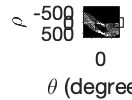

Fig =   Figure (29) with properties:

      Number: 29
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [440 378 560 420]
       Units: 'pixels'

  Show all properties


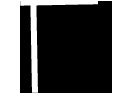

img = 513×513 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   1   1   0   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   0
   0   0   1   1   1   0   0   0   1   0   0   0   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   0
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   1   1   1   0   0   0   0   0   0

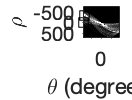

Fig =   Figure (31) with properties:

      Number: 31
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [440 378 560 420]
       Units: 'pixels'

  Show all properties


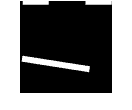

img = 513×512 logical array
   1   1   1   1   1   1   1   1   1   1   1   1   1   0   0   0   0   0   0   0   0   1   0   0   0   0   0   0   0   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0

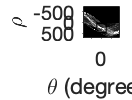

Fig =   Figure (33) with properties:

      Number: 33
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [440 378 560 420]
       Units: 'pixels'

  Show all properties


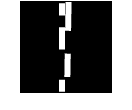

img = 513×513 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0

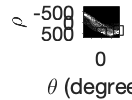

Fig =   Figure (35) with properties:

      Number: 35
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [440 378 560 420]
       Units: 'pixels'

  Show all properties


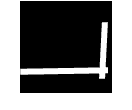



%Hough Transform for each block
n=num_img_h*num_img_v;
for iter = 1:n
img = imread(['block', num2str(iter), '.png'])
edgeCanny = edge(~img, 'canny'); % 5. Apply Canny Edge detection for each block
[H, theta, rho] = hough(edgeCanny); % 6. Apply Hough Transform

% Show Hough space
figure,imshow(imadjust(rescale(H)), [], 'XData', theta, 'YData', rho, 'InitialMagnification', 'fit');
xlabel('\theta (degrees)'); ylabel('\rho');
axis on; axis normal; hold on;

%colormap(gca,gray);
%Assume we find two lines
NumOfLines=2;
P = houghpeaks(H, NumOfLines, 'threshold', ceil(0.69*max(H(:))));

    %Superimpose a plot on the image of the transform that identifies the peaks
x = theta(P(:,2));
y = rho(P(:,1));
plot(x,y,'s','color','black');

lines = houghlines(edgeCanny,theta,rho, P, 'FillGap',50,'MinLength',40);

rty = zeros(size(img));

%figure, imshow(img), hold on

Fig = figure, imshow(rty), hold on
for k = 1:length(lines)
    xy = [lines(k).point1; lines(k).point2];
    plot(xy(:,1),xy(:,2),'LineWidth',3,'Color','white');
    %imwrite(img, "detected1-1.png")
end
%save each block with line detection as "block" 
%corresponding to the order number
saveas(Fig,['block_result', num2str(iter), '.png']); 
w = imread(['block_result', num2str(iter), '.png']);
%w = imcrop(w, [117 6 1066 1066]);     %2*2 blocks
%w = imcrop(w, [117 4 612 712]);    %3*3 blocks
w = imcrop(w, [118 5 531 532]);    %4*4 blocks
w = imresize(w,size(img));
imwrite(w,['block_result', num2str(iter), '.png']);
end

% 7. Combining the image

%This code is when we divided the image into 4*4 blocks i.e 16 blocks



d1 = imread('block_result1.png');
d2 = imread('block_result2.png');
d3 = imread('block_result3.png');
d4 = imread('block_result4.png');
d5 = imread('block_result5.png');
d6 = imread('block_result6.png');
d7 = imread('block_result7.png');
d8 = imread('block_result8.png');
d9 = imread('block_result9.png');
d10 = imread('block_result10.png');
d11 = imread('block_result11.png');
d12 = imread('block_result12.png');
d13 = imread('block_result13.png');
d14 = imread('block_result14.png');
d15 = imread('block_result15.png');
d16 = imread('block_result16.png');

%Concatenate each block horizontally
first = [d1,d2,d3,d4]; 
second = [d5,d6,d7,d8];
third = [d9,d10,d11,d12];
fourth = [d13,d14,d15,d16];

%Resize for each element
size(first)

ans =          513        2051           3


size(second)

ans =          513        2051           3


size(third)

ans =          512        2051           3


size(fourth)

ans =          513        2051           3


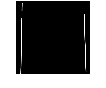


%Concatenate vertically to recover the original
result = [first;second;third;fourth];
imshow(result); title("result");

imwrite(result,'result.jpg');




%This code is when we divided the image into 2*2 blocks i.e 4 blocks


%{

d1 = imread('block_result1.png');
d2 = imread('block_result2.png');
d3 = imread('block_result3.png');
d4 = imread('block_result4.png');

first = [d1,d2];
second = [d3,d4];


size(first)
size(second)


result = [first;second];
imshow(result); title("full");
imwrite(result,'results/divisions2/W107b/result.jpg');
%}


%This code is when we divided the image into 3*3 blocks i.e 9 blocks



%{
d1 = imread('block_result1.png');
d1 = imcrop(d1, [117 4 612 712]);
a = imread("temp1.png");
d1 = imresize(d1,size(a));

d2 = imread('block_result2.png');
d2 = imcrop(d2, [117 4 612 712]);
a = imread("temp2.png");
d2 = imresize(d2,size(a));

d3 = imread('block_result3.png');
d3 = imcrop(d3, [117 4 612 712]);
a = imread("temp3.png");
d3 = imresize(d3,size(a));

d4 = imread('block_result4.png');
d4 = imcrop(d4, [117 4 612 712]);
a = imread("temp4.png");
d4 = imresize(d4,size(a));

d5 = imread('block_result5.png');
d5 = imcrop(d5, [117 4 612 712]);
a = imread("temp5.png");
d5 = imresize(d5,size(a));

d6 = imread('block_result6.png');
d6 = imcrop(d6, [117 4 612 712]);
a = imread("temp6.png");
d6 = imresize(d6,size(a));

d7 = imread('block_result7.png');
d7 = imcrop(d7, [117 4 612 712]);
a = imread("temp7.png");
d7 = imresize(d7,size(a));

d8 = imread('block_result8.png');
d8 = imcrop(d8, [117 4 612 712]);
a = imread("temp8.png");
d8 = imresize(d8,size(a));

d9 = imread('block_result9.png');
d9 = imcrop(d9, [117 4 612 712]);
a = imread("temp9.png");
d9 = imresize(d9,size(a));
%}

%{
d1 = imread('block_result1.png');
d2 = imread('block_result2.png');
d3 = imread('block_result3.png');
d4 = imread('block_result4.png');
d5 = imread('block_result5.png');
d6 = imread('block_result6.png');
d7 = imread('block_result7.png');
d8 = imread('block_result8.png');
d9 = imread('block_result9.png');

first = [d1,d2,d3];
second = [d4,d5,d6];
third = [d7,d8,d9];

size(first)
size(second)
size(third)

result = [first;second;third];
imshow(result); title("result");
imwrite(result,'result.jpg');
%}
